## Prepare Training Data

load('C:\Users\teozk\repos\maglev-master\data\teo_data_1.mat');
load('C:\Users\teozk\repos\maglev-master\data\teo_data_2.mat');
load('C:\Users\teozk\repos\maglev-master\data\teo_data_3.mat');
load('C:\Users\teozk\repos\maglev-master\data\teo_data_4.mat');
dataset_1 = teo_data_1;
dataset_2 = teo_data_2;
dataset_3 = teo_data_3;
dataset_4 = teo_data_4;

downsample_rate = 2

downsample_rate = 2


% Prepare training set
current_coil1 = [dataset_1.Y(3).Data, dataset_2.Y(3).Data, dataset_4.Y(3).Data];
current_coil1 = downsample(current_coil1, downsample_rate);
current_coil2 = [dataset_1.Y(4).Data, dataset_2.Y(4).Data, dataset_4.Y(4).Data];
current_coil2 = downsample(current_coil2, downsample_rate);
current_coil3 = [dataset_1.Y(5).Data, dataset_2.Y(5).Data, dataset_4.Y(5).Data];
current_coil3 = downsample(current_coil3, downsample_rate);
current_coil4 = [dataset_1.Y(6).Data, dataset_2.Y(6).Data, dataset_4.Y(6).Data];
current_coil4 = downsample(current_coil4, downsample_rate);
gap_1 = [dataset_1.Y(12).Data, dataset_2.Y(12).Data, dataset_4.Y(12).Data];
gap_1 = downsample(gap_1, downsample_rate);
gap_2 = [dataset_1.Y(13).Data, dataset_2.Y(13).Data, dataset_4.Y(13).Data];
gap_2 = downsample(gap_2, downsample_rate);
gap_3 = [dataset_1.Y(14).Data, dataset_2.Y(14).Data, dataset_4.Y(14).Data];
gap_3 = downsample(gap_3, downsample_rate);
gap_4 = [dataset_1.Y(15).Data, dataset_2.Y(15).Data, dataset_4.Y(15).Data];
gap_4 = downsample(gap_4, downsample_rate);

u = [current_coil1; current_coil2; current_coil3; current_coil4];
y = [gap_1; gap_2; gap_3; gap_4];

% Prepare validation set
uval_1 = dataset_3.Y(3).Data(1:15000);
uval_1 = downsample(uval_1, downsample_rate);
uval_2 = dataset_3.Y(4).Data(1:15000);
uval_2 = downsample(uval_2, downsample_rate);
uval_3 = dataset_3.Y(5).Data(1:15000); 
uval_3 = downsample(uval_3, downsample_rate);
uval_4 = dataset_3.Y(6).Data(1:15000);
uval_4 = downsample(uval_4, downsample_rate);

yval_1 = dataset_3.Y(12).Data(1:15000);
yval_1 = downsample(yval_1, downsample_rate);
yval_2 = dataset_3.Y(13).Data(1:15000);
yval_2 = downsample(yval_2, downsample_rate);
yval_3 = dataset_3.Y(14).Data(1:15000);
yval_3 = downsample(yval_3, downsample_rate);
yval_4 = dataset_3.Y(15).Data(1:15000);
yval_4 = downsample(yval_4, downsample_rate);

uval = [uval_1; uval_2; uval_3; uval_4];
yval = [yval_1; yval_2; yval_3; yval_4];

## Create and Train Network

numResponses = 4;
featureDimension = 4;
numHiddenUnits = 100;
maxEpochs = 1000;
miniBatchSize = 100;

Networklayers = [sequenceInputLayer(featureDimension) ...
    lstmLayer(numHiddenUnits) ...
    lstmLayer(numHiddenUnits) ...
    fullyConnectedLayer(numResponses) ...
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'GradientThreshold',10, ...
    'Shuffle','once', ...
    'Plots','training-progress',...
    'ExecutionEnvironment','gpu',...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',100,...
    'Verbose',0,...
    'ValidationData',[{uval} {yval}]);

poolobj = parpool;

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


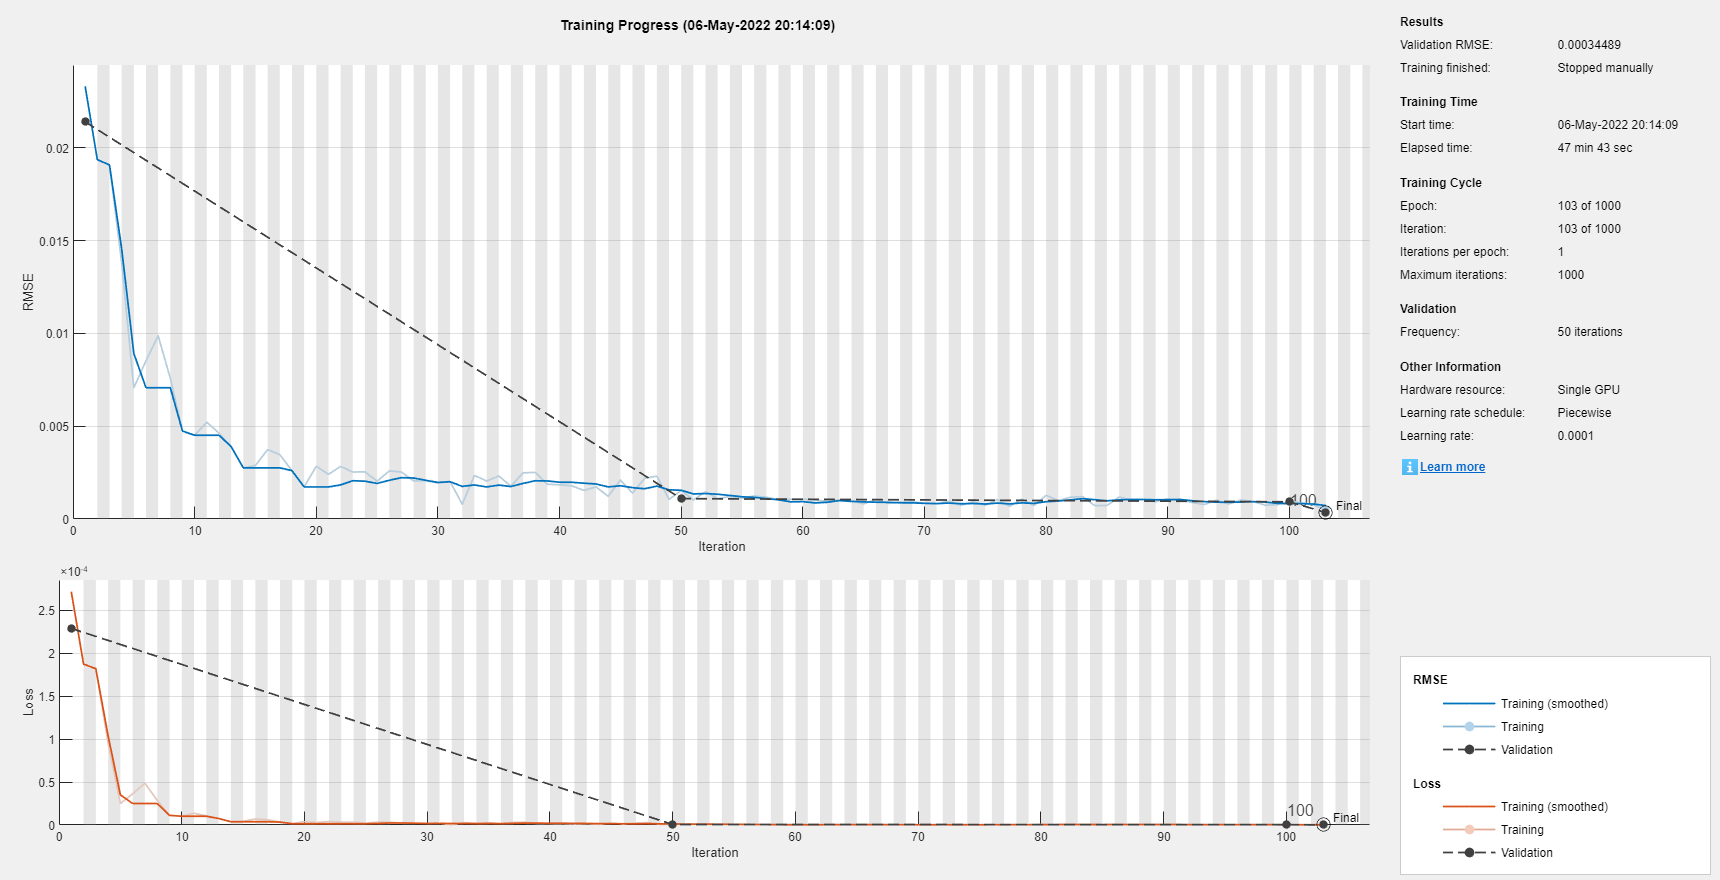

Error using save
Variable 'fourthOrderNet_serious_training' not found.

fourthOrderNet = trainNetwork(u,y,Networklayers,options);
delete(poolobj)
save('fourthOrderMdlnet_serious_training','fourthOrderNet_serious_training','u','y');

## Evaluate Model Performance


% Prepare validation set
ueval_1 = dataset_3.Y(3).Data(15000:end);
ueval_2 = dataset_3.Y(4).Data(15000:end);
ueval_3 = dataset_3.Y(5).Data(15000:end); 
ueval_4 = dataset_3.Y(6).Data(15000:end);

yeval_1 = dataset_3.Y(12).Data(15000:end);
yeval_2 = dataset_3.Y(13).Data(15000:end);
yeval_3 = dataset_3.Y(14).Data(15000:end);
yeval_4 = dataset_3.Y(15).Data(15000:end);

ueval = [downsample(ueval_1, downsample_rate); downsample(ueval_2, downsample_rate); downsample(ueval_3, downsample_rate); downsample(ueval_4, downsample_rate)];
yeval = [downsample(yeval_1, downsample_rate); downsample(yeval_2, downsample_rate); downsample(yeval_3, downsample_rate);downsample(yeval_4, downsample_rate)];



fourthOrderMixedNetStep = predict(fourthOrderNet,ueval);

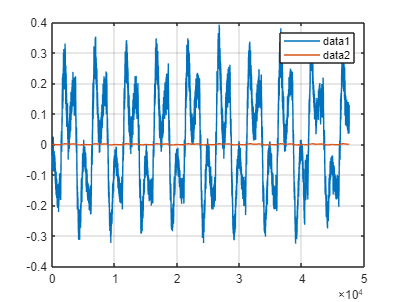


figure
plot(downsample(ueval_1, downsample_rate))
grid on

hold on
plot(downsample(yeval_1, downsample_rate))
legend